# Solución de ecuaciones diferenciales de orden superior

Un métodopara resolver ecuaciones diferenciales de orden superior es el de coeficientes indeterminados. Por ejemplo:


$${y}''+p(t){y}'+1(t)y=g(t)$$


La principal ventaje de este método es que  reduce el problema a uno de tipo algebraico. Mientras que su principal desventaja es que solo se puede utilizar para $g(t)$ simples.

Ahora, para el caso de ecuaciones no-homogéneas, se debe obtener una solución general ($y_c(t)$) tomando la expresión como homogénea y otra particular ($y_p(t)$)  para el caso de $g(t)$. Donde la solución de la expresión no homogénea será la suma de ambas soluciones ($y(t)= y_c(t)+y_p(t)$).

Algunas funciones básica para $g(t)$:

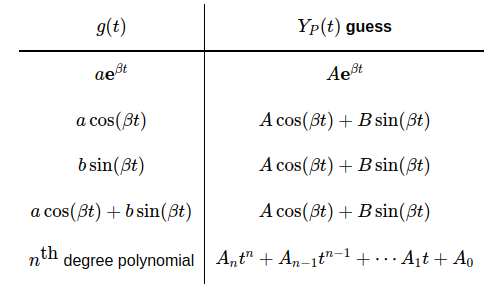

**Tabla 1. **Obtenida de [[1]](https://tutorial.math.lamar.edu/classes/de/undeterminedcoefficients.aspx)

**1.** Solución de ecuación homogénea $\ddot{y}+3\dot{y}+2y=0$ con:

- 
$$y(0)=0$$


- 
$$\dot{y}(0)=0$$


**Solución analítica: **


$$\begin{array}{rcl}
\lambda^2e^{\lambda t}+3\lambda e^{\lambda t} + 2e^{\lambda t}&=&0\\
e^{\lambda t}(\lambda+2)(\lambda+1)&=&0
\end{array}$$


con $\lambda=-1$ y $\lambda=-2$ tenemos que la solución es 


$$y = c_1e^{-t} + c_2e^{-2t}$$


%definir variables simbolicas
syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);   %2do orden
Dy = diff(y,t,1);   %1er orden
%Ecuacion diferencial
ecu = Dy2 + 3*Dy + 2*y == 0

$$ecu(t) = \frac{\partial^{2}}{\partial t^{2}}y\left(t\right)+3\,\frac{\partial }{\partial t}y\left(t\right)+2\,y\left(t\right)=0$$

%solucion general
dsolve(ecu)

$$ans = C_{1}\,{\mathrm{e}}^{-2\,t}+C_{2}\,{\mathrm{e}}^{-t}$$

%Condiciones iniciales
CI1 = y(0) == 0;
CI2 = Dy(0) == 0;
%Solucion con CI
Sol1 = dsolve(ecu, [CI1 CI2])

$$Sol1 = 0$$

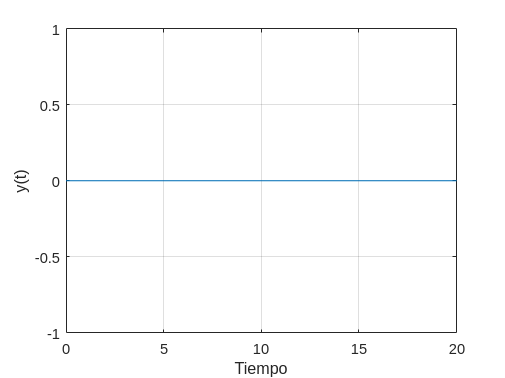

%Grafico de la sln
fplot(Sol1,[0 20])
grid on
xlabel("Tiempo")
ylabel("y(t)")

**2. **Solución a ecuación no-homogénea $\ddot{y}+3\dot{y}+2y=t+1$ con

- 
$$y(0)=0$$


- 
$$\dot{y}(0)=0$$


**Solución analítica:**

Por ejercicio anterior sabemos que $y = c_1e^{-t} + c_2e^{-2t}$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&at+b\\[5pt]
y^{'}_p&=&a\\[5pt]
y^{''}_p&=&0\\[5pt]
{y}''_p + 3{y}'_p + 2{y}_p&=&0+3a+2(at+b)
\end{array}$$


Luego, para despejar $a$ y $b$ utilizamos la igualdad $0+3a+2(at+b) = t+1$


$$\begin{array}{rcl}
3a+2b &=& 1\\
2at &=& t
\end{array}$$


Con lo cual $a=1/2$ y $b=-1/4$


$$y_p=1/2t-1/4$$


 
$$\begin{array}{rcl}
y &=& y_c + y_p\\
  &=& c_1e^{-t} + c_2e^{-2t} + \frac{1}{2}t - \frac{1}{4}
\end{array}$$
       

syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);  %2do orden
Dy = diff(y,t,1);   %1er orden
%Ecuacion diferencial
eq1 = Dy2 + 3*Dy + 2*y == t+1;
%solucion general
dsolve(eq1)

$$ans = \frac{t}{2}+C_{1}\,{\mathrm{e}}^{-2\,t}+C_{2}\,{\mathrm{e}}^{-t}-\frac{1}{4}$$

%Condiciones iniciales
CI1 = y(0)==0; CI2 = Dy(0)==0;
%Solucion con CI
Sol2 = dsolve(eq1,[CI1,CI2])

$$Sol2 = \frac{t}{2}+\frac{{\mathrm{e}}^{-2\,t}}{4}-\frac{1}{4}$$

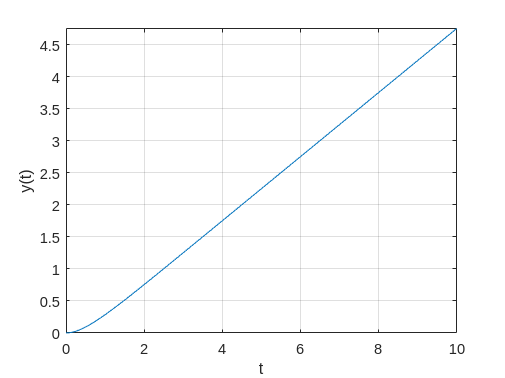

%Grafico de la sln
figure
fplot(Sol2,[0 10])
grid on
xlabel('t')
ylabel('y(t)')

**3. **Solución a ecuación no-homogénea $\ddot{y}+3\dot{y}+2y=e^{-t}$ con

- 
$$y(0)=0$$


- 
$$\dot{y}(0)=0$$


**Solución analítica:**

Por ejercicio anterior sabemos que $y = c_1e^{-t} + c_2e^{-2t}$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&ate^{-t}\\[5pt]
y^{'}_p&=&-a(t-1)e^{-t}\\[5pt]
y^{''}_p&=&a(t-2)e^{-t}\\[5pt]
{y}''_p + 3{y}'_p + 2{y}_p&=&a(t-2)e^{-t}-3a(t-1)e^{-t}+2ate^{-t}
\end{array}$$


 Luego, para despejar $a$ y $b$ utilizamos la igualdad $a(t-2)e^{-t}-3a(t-1)e^{-t}+2ate^{-t}= e^{-t}$


$$\begin{array}{rcl}
ate^{-t} &=& te^{-t}\\
a &=& 1
\end{array}$$


Con lo cual $y_p=e^{-t}$ :


$$y= c_1e^{-t} + c_2e^{-2t} +te^{-t}$$


syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);  %2do orden
Dy = diff(y,t,1);   %2do orden
%Ecuacion diferencial
eq1 = Dy2 + 3*Dy + 2*y == exp(-t);
%solucion general
dsolve(eq1);
%Condiciones iniciales
CI1 = y(0)==0; CI2 = Dy(0)==0;
%Solucion con CI
Sol3 = dsolve(eq1,[CI1,CI2])

$$Sol3 = {\mathrm{e}}^{-2\,t}\,\left(t\,{\mathrm{e}}^{t}-{\mathrm{e}}^{t}+1\right)$$

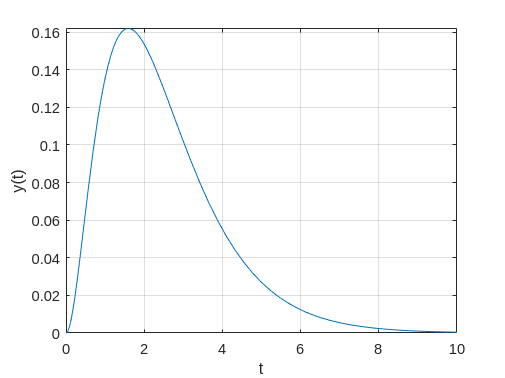

%Grafico de la sln
figure
fplot(Sol3,[0 10])
grid on
xlabel('t')
ylabel('y(t)')

**Gráfico en conjunto de soluciones de puntos 1., 2., 3.**

Note como la entrada al sistema genera cambios en la dinámica de la solución

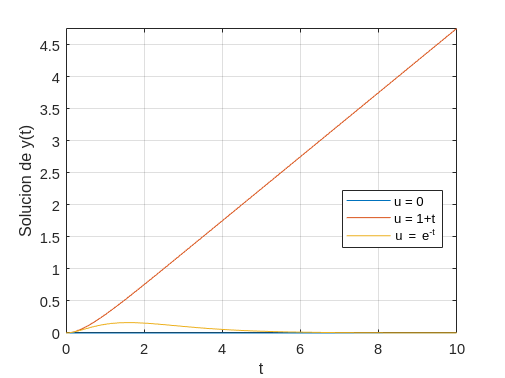

figure
fplot(Sol1, [0 10])
grid on
hold on
fplot(Sol2, [0 10])
fplot(Sol3,[0 10])
xlabel("t")
ylabel("Solucion de y(t)")
legend("u = 0","u = 1+t","u = e^{-t}","Location","best")

**4.** Solución a ecuación homogénea $\ddot{y} +4y=0$ con

- 
$$y(0)=1
$$


- 
$$\dot{y}(0)=0
$$


**Solución analítica:**


$$\begin{array}{rcl}
\lambda^2e^{\lambda t} + 4 \lambda e^{\lambda t} &=& 0\\[5pt]
e^{\lambda t}(\lambda^2 + 4 \lambda) &=& 0
\end{array}


$$
 

 con $\lambda=-2i$ y $\lambda=2i$ tenemos que la solución es $y = c_1e^{-2ti}+c_2e^{2ti}$

Aplicando la igualdad de euler $e^{\alpha +i\beta} = e^{\alpha}\cos(\beta)+ie^{\beta}\sin(\beta)$:


$$\begin{array}{rcl}
y &=& c_1(\cos(2t)+i\sin(2t))+c_2(\cos(2t)-i\sin(2t))\\[15pt]
 &=& (c_1+c_2)\cos(2t)+ i (c_1-c_2)\sin(2t)\\[15pt]
 &=& C_1\cos(2t)+ C_2\sin(2t)\\[15pt]
\end{array}$$


syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);  %1er orden
%Ecuacion diferencial
eq1 = Dy2 + 4*y == 0;
%solucion general
dsolve(eq1)

$$ans = C_{1}\,\cos\left(2\,t\right)-C_{2}\,\sin\left(2\,t\right)$$

%Condiciones iniciales
CI1 = y(0)==1; CI2 = Dy(0)==0;
%Solucion con CI
Sol1 = dsolve(eq1,[CI1,CI2])

$$Sol1 = \cos\left(2\,t\right)$$

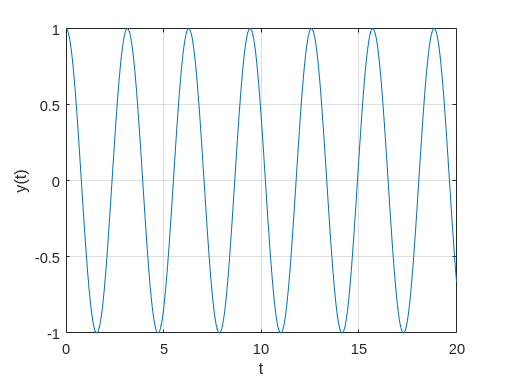

figure
fplot(Sol1,[0 20])
grid on
xlabel('t')
ylabel('y(t)')

**5.** Solución a ecuación no-homogénea $\ddot{y} + 4y = 1 + \sin{t}$ con 

- 
$$y(0)=1
$$


- 
$$\dot{y}(0)=0
$$


Por ejercicio anterior sabemos que $y =C_1\cos(2t)+ C_2\sin(2t)$ 

Ahora, vamos a obtener la solución particular $y_p(t)$:


$$\begin{array}{rcl}
y_p&=&a\sin t +b \cos t\\[5pt]
y^{'}_p&=&a\cos t - b \sin t\\[5pt]
y^{''}_p&=&-a\sin t - b \cos t\\[5pt]
y^{''}_p+4y_p&=&-a\sin t - b \cos t+ 4(a\sin t +b \cos t)
\end{array}$$


 Luego, para despejar $a$ y $b$ utilizamos la igualdad $3a\sin t+3b\cos t = \sin(t)$


$$\begin{array}{rcl}
a &=& 1/3\\
b &=& 0
\end{array}$$


Con lo cual $y_p=\frac{1}{3}\sin t$ :


$$y= C_1\cos(2t)+ C_2\sin(2t) + \frac{1}{3}\sin t$$


syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);  %1er orden
%Ecuacion diferencial
eq1 = Dy2 + 4*y == 1+sin(t);
%solucion general
dsolve(eq1);
%Condiciones iniciales
CI1 = y(0)==1; CI2 = Dy(0)==0;
%Solucion con CI
sympref("FloatingPointOutput",false);
Sol2 = simplify(dsolve(eq1,[CI1,CI2]))

$$Sol2 = \frac{3\,{\cos\left(t\right)}^{2}}{2}-\frac{\sin\left(t\right)\,\cos\left(t\right)}{3}+\frac{\sin\left(t\right)}{3}-\frac{1}{2}$$

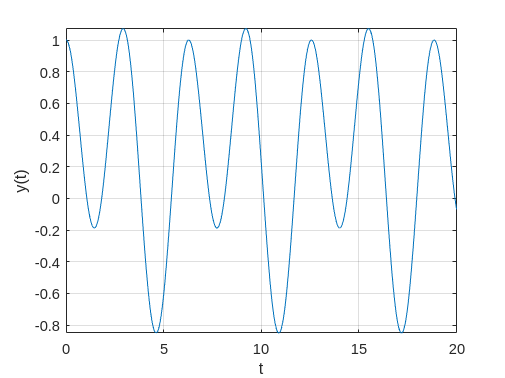

figure
fplot(Sol2,[0 20])
grid on
xlabel('t')
ylabel('y(t)')

**6.** Solución a ecuación no-homogénea $\ddot{y} + 4y = 1 + \sin{2t}$ con 

- 
$$y(0)=1
$$


- 
$$\dot{y}(0)=0
$$


syms y(t)
%definimos derivadas
Dy2 = diff(y,t,2);  %1er orden
%Ecuacion diferencial
eq1 = Dy2 + 4*y == 1+sin(2*t);
%solucion general
dsolve(eq1);
%Condiciones iniciales
CI1 = y(0)==1; CI2 = Dy(0)==0;
%Solucion con CI
sympref("FloatingPointOutput",false);
Sol3 = simplify(dsolve(eq1,[CI1,CI2]))

$$Sol3 = \frac{3\,\cos\left(2\,t\right)}{4}+\frac{\sin\left(2\,t\right)}{8}-\frac{t\,\cos\left(2\,t\right)}{4}+\frac{1}{4}$$

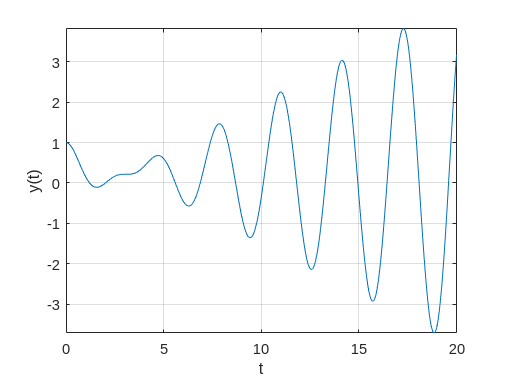

figure
fplot(Sol3,[0 20])
grid on
xlabel('t')
ylabel('y(t)')

## Resonancia:

Cuando la frecuencia interna natural $\omega_0$ coincide con la frecuencia externa natural $\omega$.


$$\ddot{y} + \omega_0^2 y  = f \cos(\omega t)$$


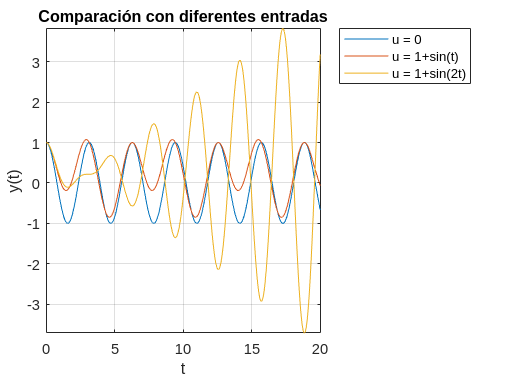

figure
fplot(Sol1,[0 20])
hold on
fplot(Sol2,[0 20])
fplot(Sol3,[0 20])
grid on
xlabel('t')
ylabel('y(t)')
title("Comparación con diferentes entradas")
legend({'u = 0','u = 1+sin(t)','u = 1+sin(2t)'},"Location","bestoutside")